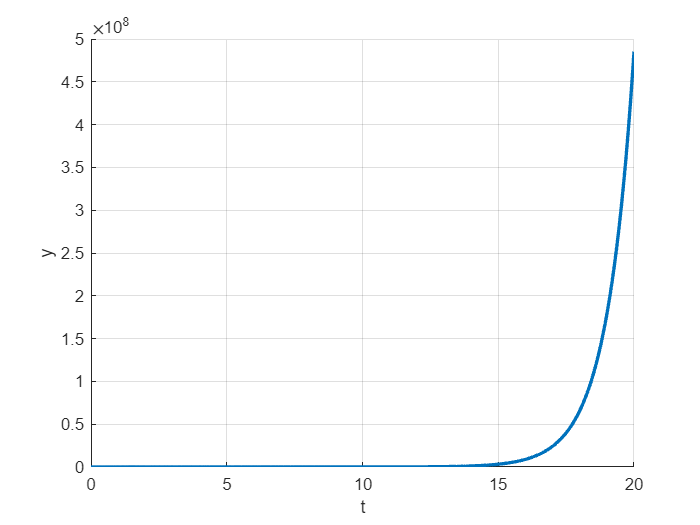

a0 = -2;
a1 = 1;
a2 = 1;
k0 = -3;
k1 = -1;
simOut = sim('L4_1.slx');
t1 = simOut.y.Time;
y1 = simOut.y.Data;

% Строим график
figure;
hold on;
plot(t1, y1, 'LineWidth', 2);
xlabel('t');
ylabel('y');
grid on;
hold off;


t2 = simOut.y1.Time;
y2 = simOut.y1.Data;

% Строим график
figure;
hold on;
% plot(t1, y1, 'LineWidth', 2);
plot(t2, y2, 'LineWidth', 2);
legend('y_{раз}', 'y_{з}')

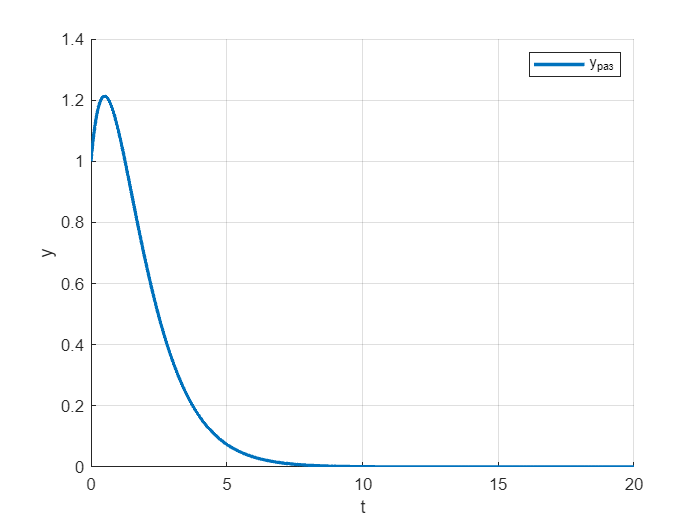

xlabel('t');
ylabel('y');
grid on;
hold off;

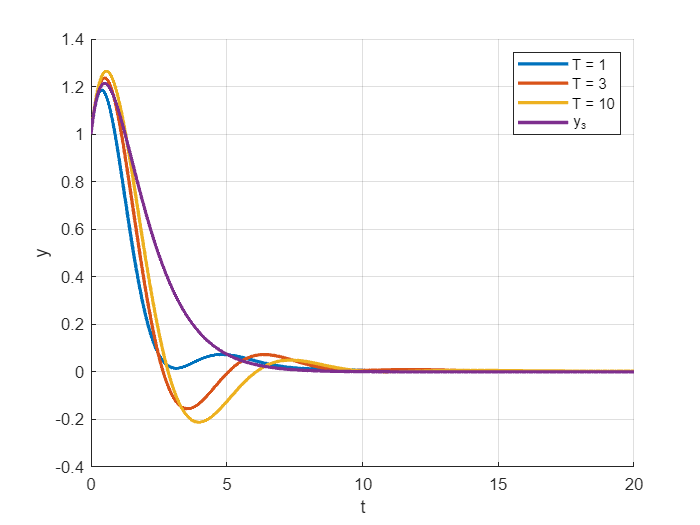

figure;
hold on;
for T = [1, 3, 10]
    simOut2 = sim("L4_1.slx");
    t3 = simOut2.y2.Time;
    y3 = simOut2.y2.Data;

    plot(t3, y3, 'LineWidth', 2);
    xlabel('t');
    ylabel('y');
    grid on;

end
t2 = simOut2.y1.Time;
y2 = simOut2.y1.Data;
plot(t2, y2, 'LineWidth', 2);
legend('T = 1', 'T = 3', 'T = 10', 'y_{з}')

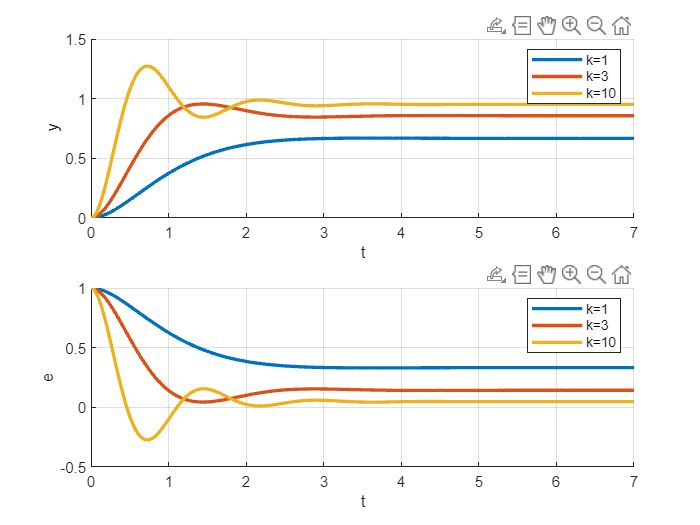

figure;

for k = [1, 3, 10]
    simOut3 = sim("L4_3.slx");
    t3 = simOut3.y3_1.Time;
    y3 = simOut3.y3_1.Data;
    g = 1;
    e = g - y3;

    % Первый график
    subplot(2, 1, 1);
    hold on;
    plot(t3, y3, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('y');
    legend('show');
    grid on;

    % Второй график
    subplot(2, 1, 2);
    hold on;
    plot(t3, e, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('e');
    grid on;
    legend('show');
end

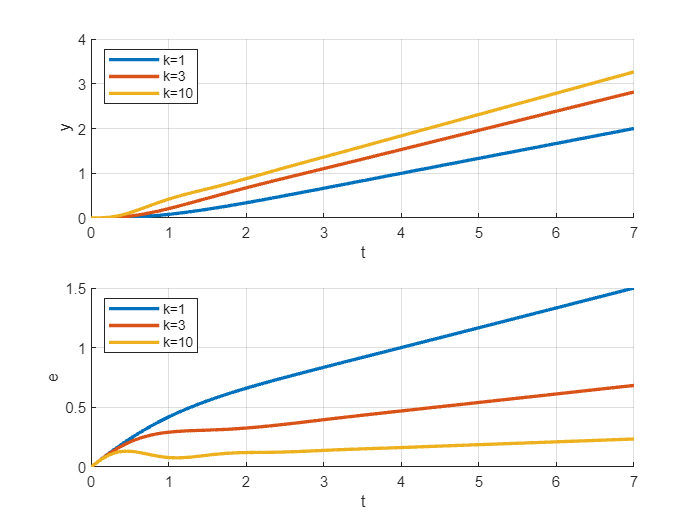


% Добавление легенды после завершения цикла


figure;

for k = [1, 3, 10]
    simOut3 = sim("L4_3.slx");
    t3 = simOut3.y3_2.Time;
    y3 = simOut3.y3_2.Data;
    g = 0.5*t3;
    e = g - y3;

    % Первый график
    subplot(2, 1, 1);
    hold on;
    plot(t3, y3, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('y');
    grid on;
    legend('show', Location='northwest');

    % Второй график
    subplot(2, 1, 2);
    hold on;
    plot(t3, e, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('e');
    grid on;
    legend('show', Location='northwest');
end

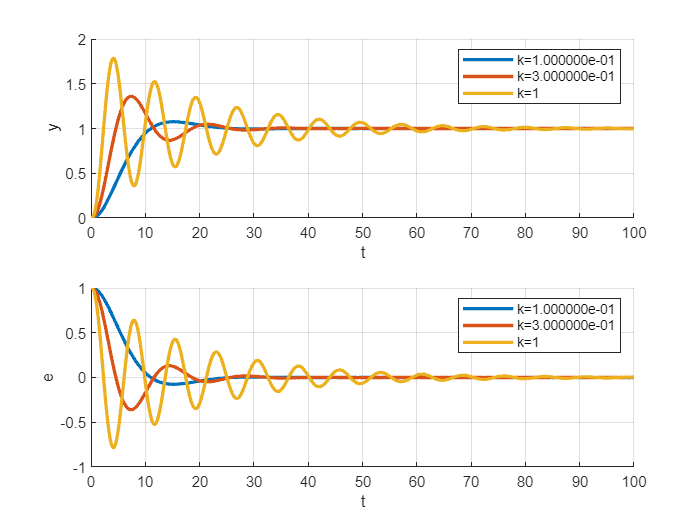

figure;

for k = [0.1, 0.3, 1]
    simOut3 = sim("L4_4.slx");
    t3 = simOut3.y4_1.Time;
    y3 = simOut3.y4_1.Data;
    g = 1;
    e = g - y3;

    % Первый график
    subplot(2, 1, 1);
    hold on;
    plot(t3, y3, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('y');
    legend('show');
    grid on;

    % Второй график
    subplot(2, 1, 2);
    hold on;
    plot(t3, e, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('e');
    legend('show');
    grid on;
end

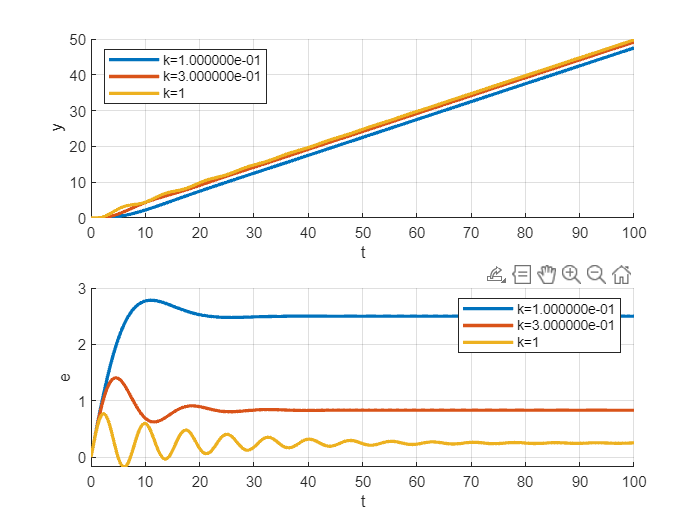


figure;

for k = [0.1, 0.3, 1]
    simOut3 = sim("L4_4.slx");
    t3 = simOut3.y4_2.Time;
    y3 = simOut3.y4_2.Data;
    g = 0.5*t3;
    e = g - y3;

    % Первый график
    subplot(2, 1, 1);
    hold on;
    plot(t3, y3, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('y');
    legend('show', Location='northwest');
    grid on;

    % Второй график
    subplot(2, 1, 2);
    hold on;
    plot(t3, e, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('e');
    legend('show');
    grid on;
end

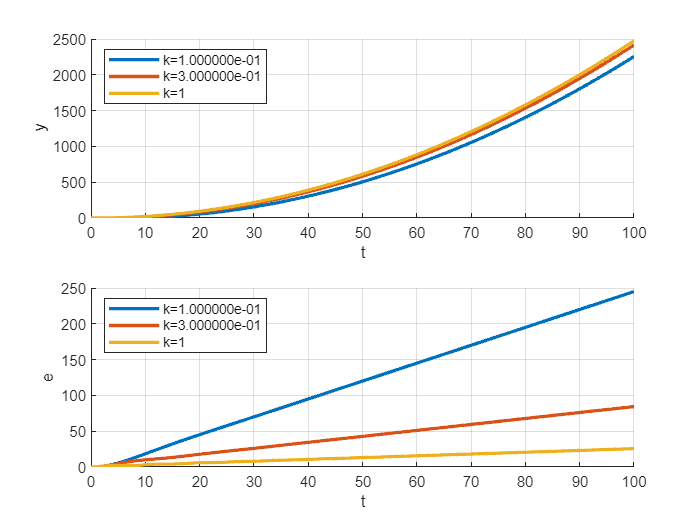



figure;

for k = [0.1, 0.3, 1]
    simOut3 = sim("L4_4.slx");
    t3 = simOut3.y4_3.Time;
    y3 = simOut3.y4_3.Data;
    g = 0.25*t3.^2;
    e = g - y3;

    % Первый график
    subplot(2, 1, 1);
    hold on;
    plot(t3, y3, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('y');
    grid on;
    legend('show', Location='northwest');

    % Второй график
    subplot(2, 1, 2);
    hold on;
    plot(t3, e, 'LineWidth', 2, 'DisplayName', sprintf('k=%d', k));
    xlabel('t');
    ylabel('e');
    legend('show', Location='northwest');
    grid on;
end

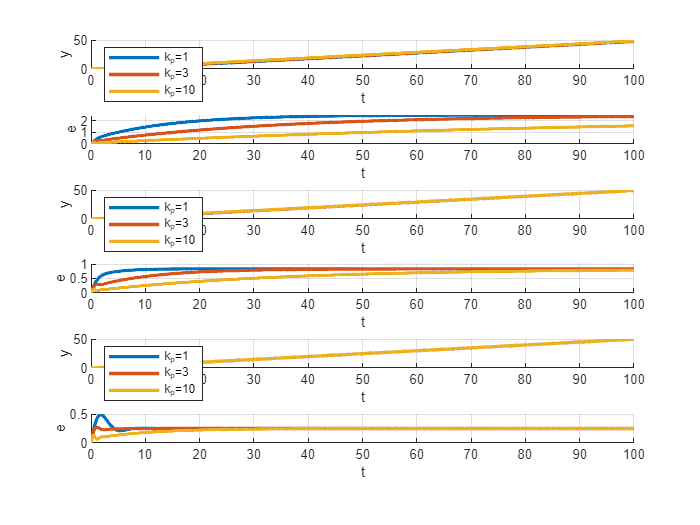

figure;

for k_i = [0.1, 0.3, 1]
    for k_p = [1, 3, 10]
        simOut3 = sim("L4_5.slx");
        t3 = simOut3.y4_1.Time;
        y3 = simOut3.y4_1.Data;
        g = 0.5 * t3;
        e = g - y3;

        % График y
        subplot(6, 1, 2 * find(k_i == [0.1, 0.3, 1]) - 1);
        hold on;
        plot(t3, y3, 'LineWidth', 2, 'DisplayName', sprintf('k_p=%d', k_p));
        xlabel('t');
        ylabel('y');
        grid on;

        % График e
        subplot(6, 1, 2 * find(k_i == [0.1, 0.3, 1]));
        hold on;
        plot(t3, e, 'LineWidth', 2, 'DisplayName', sprintf('k_i=%.1f, k_p=%d', k_i, k_p));
        xlabel('t');
        ylabel('e');
        grid on;
    end
    % Добавление легенды после завершения внутреннего цикла
    subplot(6, 1, 2 * find(k_i == [0.1, 0.3, 1]) - 1);
    legend('show', Location='northwest');

end

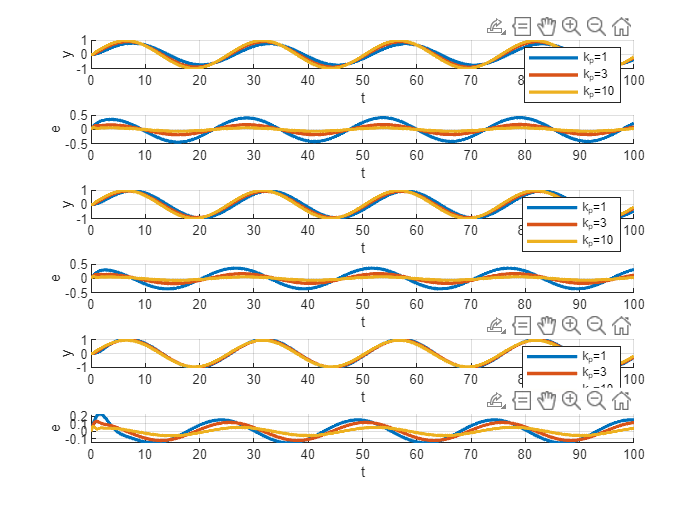


figure;

for k_i = [0.1, 0.3, 1]
    for k_p = [1, 3, 10]
        simOut3 = sim("L4_5.slx");
        t3 = simOut3.y4_2.Time;
        y3 = simOut3.y4_2.Data;
        g = sin(0.25 * t3);
        e = g - y3;

        % График y
        subplot(6, 1, 2 * find(k_i == [0.1, 0.3, 1]) - 1);
        hold on;
        plot(t3, y3, 'LineWidth', 2, 'DisplayName', sprintf('k_p=%d', k_p));
        xlabel('t');
        ylabel('y');
        grid on;

        % График e
        subplot(6, 1, 2 * find(k_i == [0.1, 0.3, 1]));
        hold on;
        plot(t3, e, 'LineWidth', 2, 'DisplayName', sprintf('k_p=%d', k_p));
        xlabel('t');
        ylabel('e');
        grid on;
    end
    % Добавление легенды после завершения внутреннего цикла
    subplot(6, 1, 2 * find(k_i == [0.1, 0.3, 1]) - 1);
    legend('show');
end

figure;
simOut3 = sim("L4_6.slx");

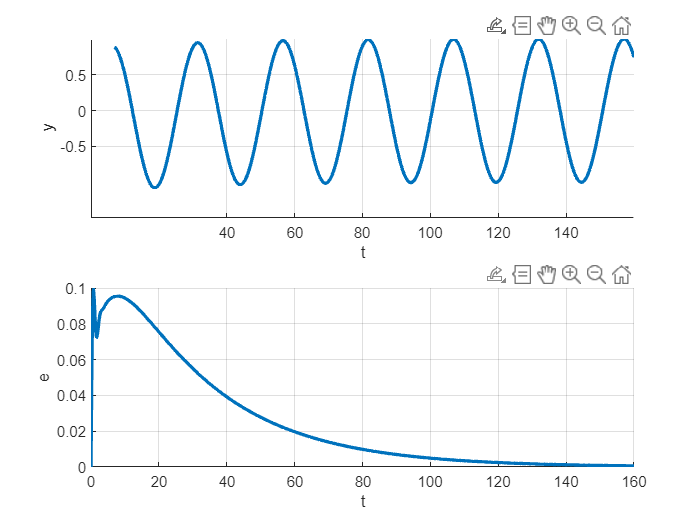

t3 = simOut3.y6.Time;
y3 = simOut3.y6.Data;
g = sin(0.25*t3);
e = g - y3;

% Первый график
subplot(2, 1, 1);
hold on;
plot(t3, y3, 'LineWidth', 2);
xlabel('t');
ylabel('y');
grid on;

% Второй график
subplot(2, 1, 2);
hold on;
plot(t3, e, 'LineWidth', 2);
xlabel('t');
ylabel('e');
grid on;

b_2 = 2;
b_1 = 2;
b_0 = 0;
f1 = 3*(1.0625+2*b_2)-(0.1875+2*b_1)

f1 = 11

f2 = 3*(1.0625+2*b_2)*(0.1875+2*b_1)-9*(0.0625+2*b_0)-(0.1875+2*b_1)^2

f2 = 45.5000